#  Analysis 1

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C226_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'release dox-',[6],2:4,1:36,[0 0 0],[0 10]; %1    
        'release dox+',[6],5:7,1:36,[0 0 0],[0 10]; %1 
        'NR dox-',[5],2:4,1:36,[0 0 0],[0 10]; %1    
        'NR dox+',[5],5:7,1:36,[0 0 0],[0 10]; %1 
    };


% load([dataDir 'sensordata.mat'],'S');
S = loadData_IF(conditions, dataDir);


conds = [1 2];


xval = 'FarRed1';

gateVals = {'FarRed1'};
rangeVals = {[2^3 2^18]}; 

figure('units','inches','pos',[0 0 4 2]), hold on
data = {};
for i = 1:length(conds)
   condition = conds(i);
    inds =  gate_vals(S(condition), gateVals, rangeVals);
    xdata = log2(S(condition).(xval)(inds));

%     edges = linspace(5,12,100);
%     [N,~] = histcounts(xdata,edges);
%     plot(edges(2:end),N/length(xdata),'Linewidth',2);
    data{i} = xdata;
end
nhist(data,'samebins','FontSize',16,'noerror','maxbins',30);

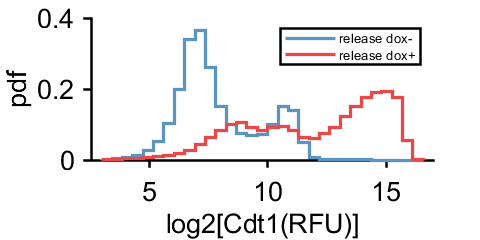

Error using matlab.graphics.internal.name (line 101)
Cannot create output file 'C:\Users\nalin\Documents\GitHub\image-analysis-ratnayeke-2022\Figure_generation\Cdt1-starve\C226\Figs\cdt1hists.pdf'.

Error in print (line 71)
pj = matlab.graphics.internal.name( pj );

Error in 

lg = legend(conditions(conds,1));
lg.FontSize = 8;
xlabel('log2[Cdt1(RFU)]')
% axis square
hold off
print_pdf([pwd() '\Figs\cdt1hists.pdf'])